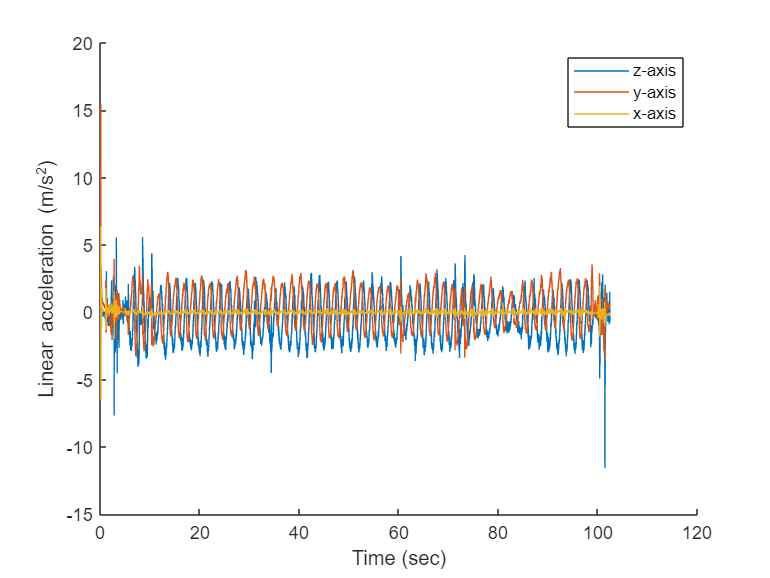

cla; clf;
hold on;
plot(x60_stat_raw(:, 1), x60_stat_raw(:, 4)); label1 = "z-axis";
plot(x60_stat_raw(:, 1), x60_stat_raw(:, 3)); label2 = "y-axis";
plot(x60_stat_raw(:, 1), x60_stat_raw(:, 2)); label3 = "x-axis";
legend(label1, label2, label3);
xlabel("Time (sec)");
ylabel("Linear acceleration (m/s^2)");
% title("Raw data");
hold off;

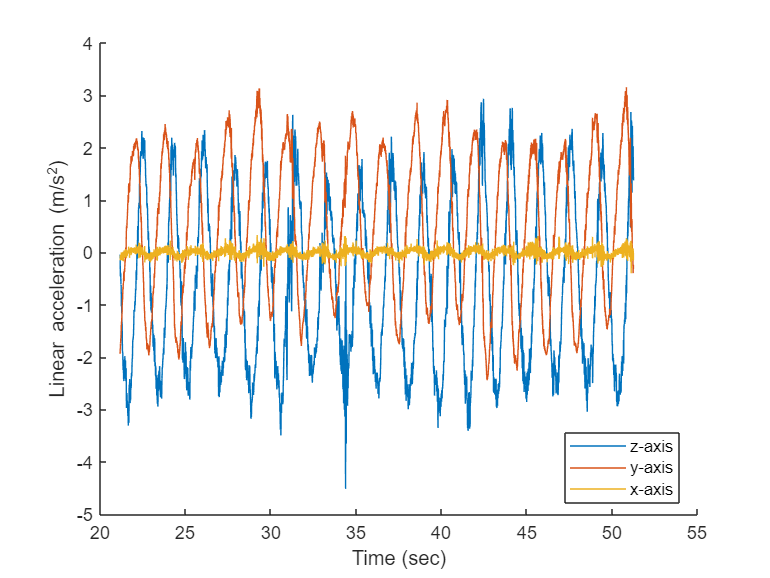

cla;clf;
hold on; 
plot(x60_stationary(:, 1), x60_stationary(:, 4)); label1 = "z-axis";
plot(x60_stationary(:, 1), x60_stationary(:, 3)); label2 = 'y-axis';
plot(x60_stationary(:, 1), x60_stationary(:, 2)); label3 = 'x-axis';
legend(label1, label2, label3, "Location", "Best");
xlabel("Time (sec)");
ylabel("Linear acceleration (m/s^2)");
hold off; 

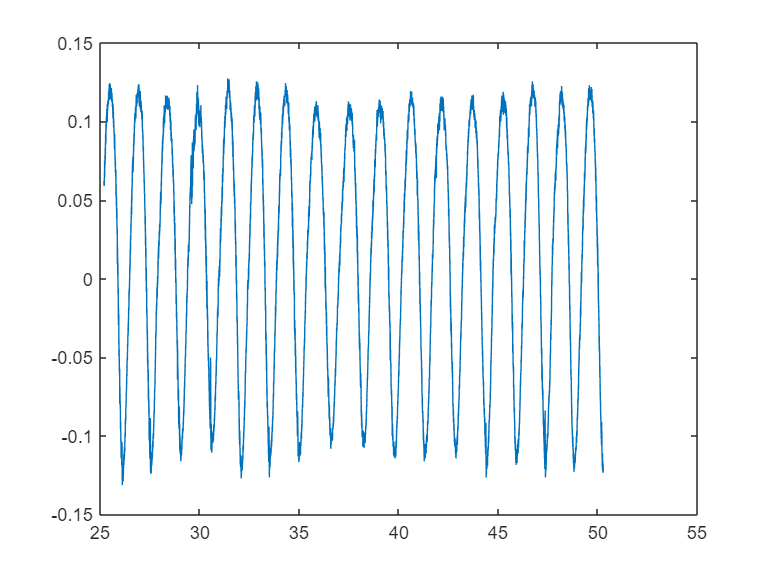

% x60_stationary(12000:end, :) = [];
% Change to just return the overall frequency
% plot(x120_stationary(1:12000, 1), x120_stationary(1:12000, 4));
plot(SlowData(10000:20000, 1), SlowData(10000:20000, 4));

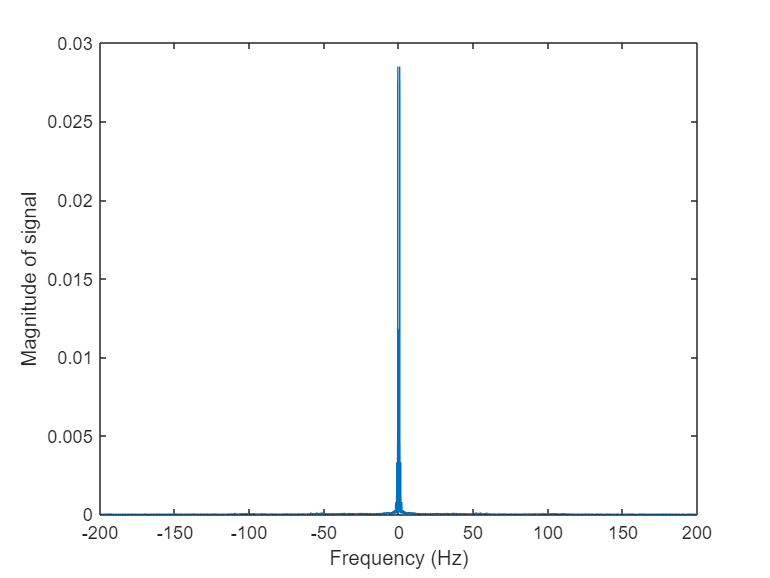

[max_amp, max_time] = max_freq_plot(SlowData);

max_amp

max_amp = 0.0285

% Since the frequency is in Hz (revolution per sec)
avg_revs = max_amp * 60 % in rev/min

avg_revs = 1.7099

target = 60; % rev/min 
margin = 3;
if (avg_revs < (target - margin))
    disp("Speed up, grandpa!");
elseif (avg_revs > (target + margin)) 
    disp("Woah, buddy! Slow down!")
else
    disp("You're doing great, sweetie :)")
end

Speed up, grandpa!
